%**************************************************************************
% \details     : digitale Signalverarbeitung - U8
% \autor       : Simon Burkhardt
% \file        : dsvgl_Aufgaben_8.mlx
% \date        : 24.05.2019
% \version     : 1.0
%**************************************************************************

# DIGITALE SIGNALVERARBEITUNG (8)

## Aufgabe 1 

Ziel dieser Aufgabe ist es, ein digitales Tiefpassfilter mit Hilfe der Fenstermethode zu entwerfen. 

Dazu verwenden wir ein Transversalfilter mit folgender Struktur [...]

Wie man leicht überprüfen kann, gilt für die z-Übertragungsfunktion dieses Filters [...]

Um die Koeffizienten hi des Filters zu bestimmen, gehen wir von einem zeitkontinuierlichen 

Tiefpassfilter mit dem Amplitudengang [...] aus. Den Phasengang wählen wir vorläufig konstant gleich null, d.h. ϕ(f) = 0. Daraus folgt, dass die Übertragungsfunktion H(f) rein reell ist. 

### a) Skizzieren Sie den gegebenen Amplitudengang. 

clear all; clc; format shorteng;
fg = 1;


### b) Bestimmen und skizzieren Sie die Impulsantwort h(t) des zeitkontinuierlichen Filters. Ist das Filter kausal? Kann das Filter durch Verschieben der Impulsantwort kausal gemacht werden? 

Die Abtastung der Impulsantwort h(t) mit der Rate fS = 8⋅fg ergibt die Abtastwerte h[k] = h(k/fS).

### c) Berechnen und plotten Sie mit Hilfe von MATLAB die Abtastwerte h[k] der Impulsantwort h(t) im Bereich -20 ≤ k ≤ +20. 

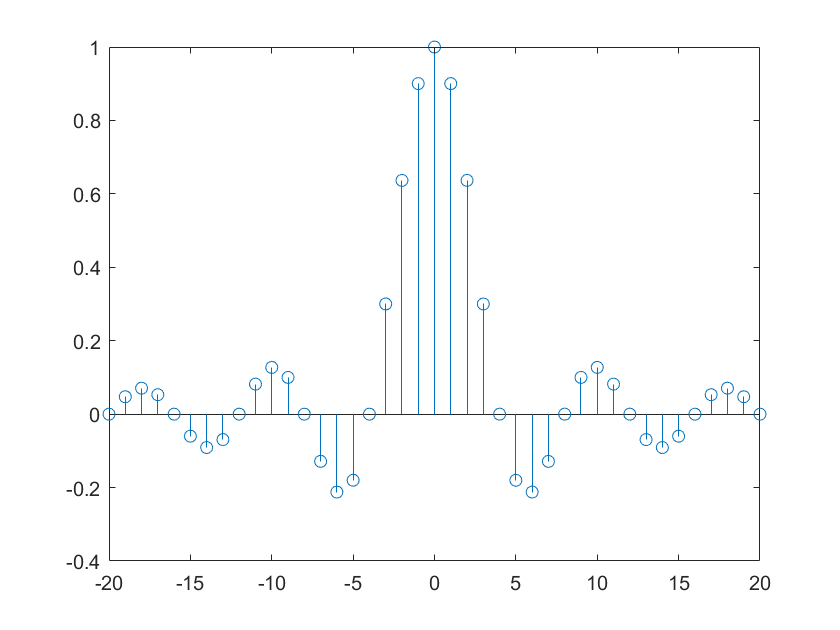

% fs = fg*8;
Ts = 1/fs;
k = -20:20;
% t = k*Ts+eps;
t = k*Ts;

h = sin(2*pi*fg*t)./(pi*t);
h(21)=2*fg; %Definieren des Wertes für k=0 
h = h/(2*fg);  % Skalierungsfaktor

stem(k,h)

### d) Um wie viele Abtastwerte müssen die unter c) berechneten L = 41 Werte verschoben werden, damit ein kausales Filter resultiert? 

L = length(k);
offset = (L-1)/2

offset =     20.0000e+000


offset = 19;

### e) Lassen Sie sich mit dem MATLAB-Befehl fvtool den Amplitudengang des Filters anzeigen. Als Filterkoeffizienten hi verwenden Sie dazu die unter c) berechneten L = 41 Abtastwerte der Impulsantwort. Sind Sie mit dem Resultat zufrieden? 

**Tipp**: Um ein Filter mit fvtool zu analysieren, müssen Sie Folgendes im MATLAB Command Window eingeben: 

Zaehler = [b0 b1 b2 ... ]; Koeffizienten des Zählerpolynoms von H(z) 

Nenner = [a0 a1 a2 ...]; Koeffizienten des Nennerpolynoms von H(z) 

fvtool(Zaehler, Nenner); 

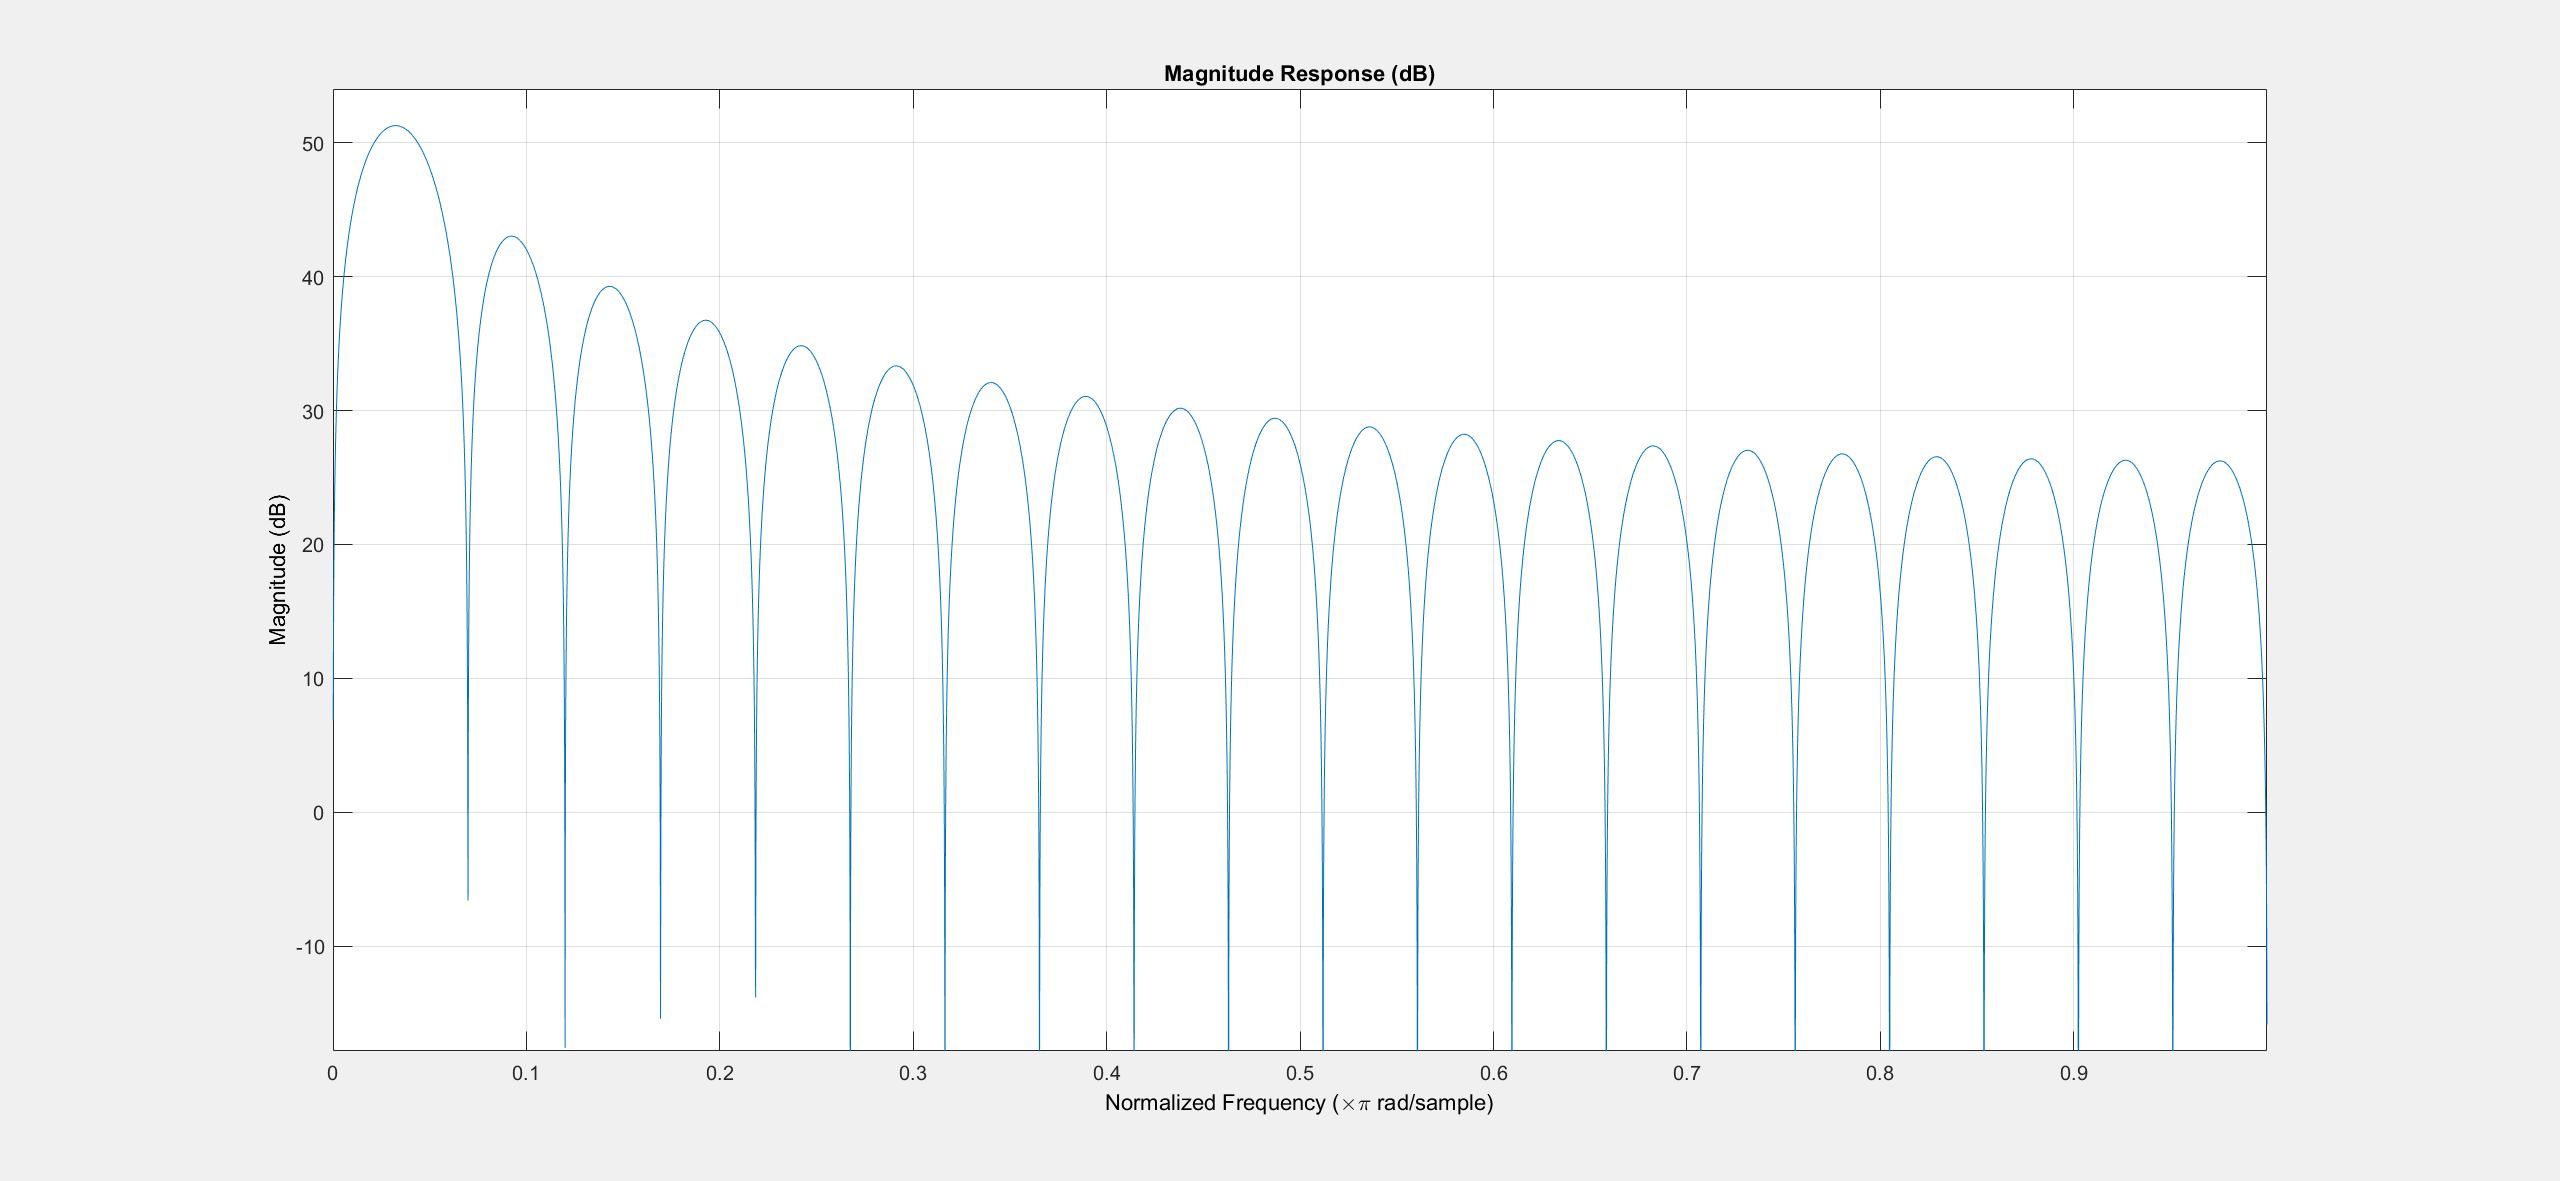

fvtool(k)

Um das Resultat zu verbessern, soll nun h[k] mit einem Hamming-Fenster der Länge L = 41 gewichtet werden.

### f) Berechnen Sie die Gewichtungskoeffizienten des Hamming-Fensters mit Hilfe des MATLAB-Befehls hamming. Verwenden Sie stem um die Koeffizienten zu plotten.

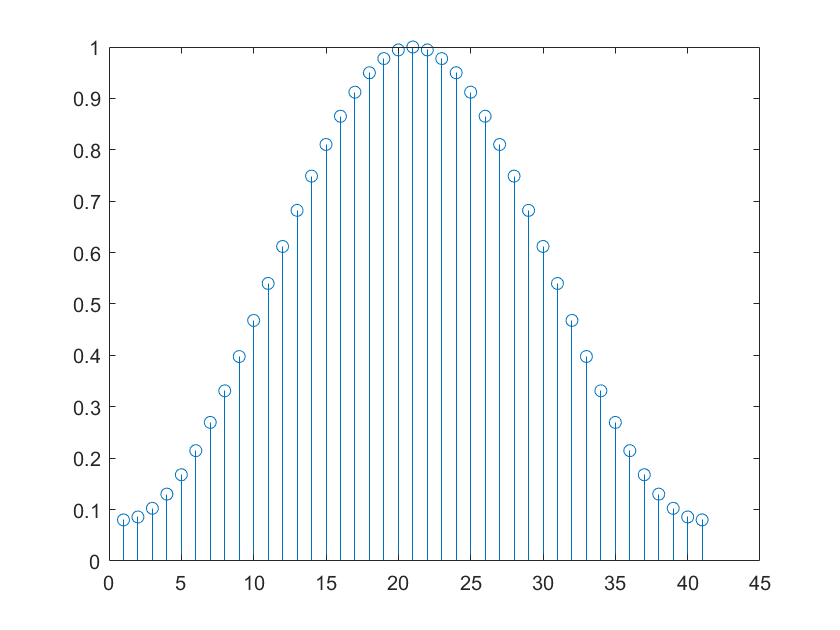

w = hamming(L);
stem(w)

### g) Berechnen Sie neue Filterkoeffizienten, indem Sie h[k] elementweise mit den Koeffizienten des Hamming-Fensters multiplizieren.

hw = h.*w';

### h) Verwenden Sie den MATLAB-Befehl fvtool, um den Amplitudengang des Filters zu plotten. Welche Unterschiede zu e) fallen Ihnen auf? 

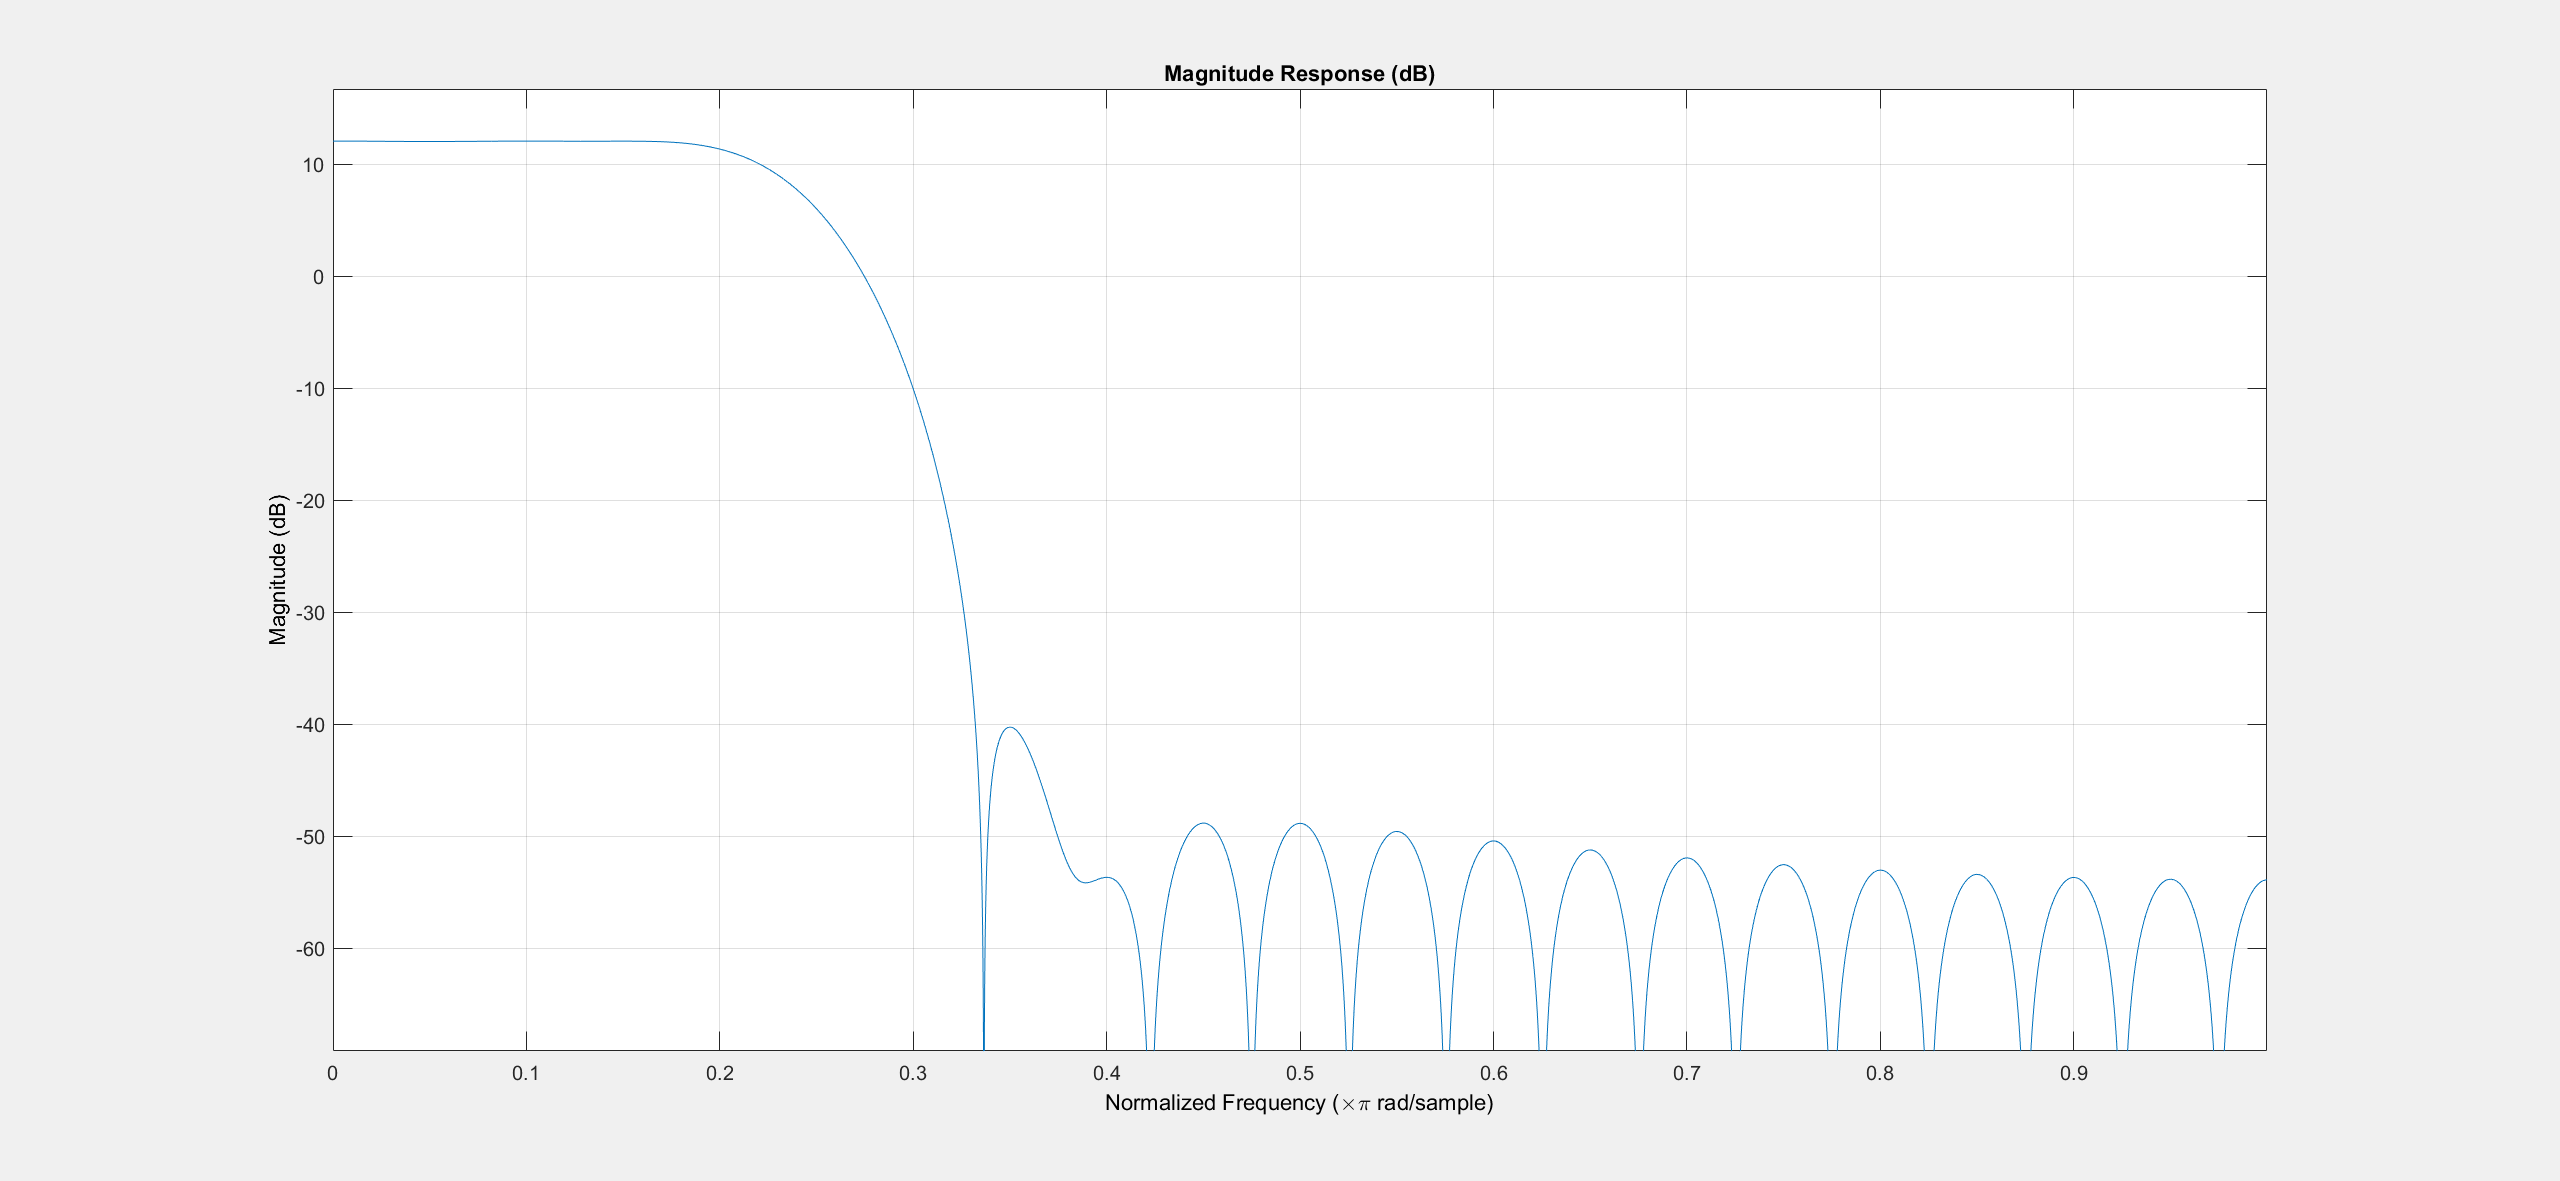

fvtool(hw)

P.S.: Wie viele Pole hat das Filter und wo liegen sie?

## Aufgabe 2

Ein idealer, bandbegrenzter Differentiator besitzt die Impulsantwort [...]

wobei fg die Grenzfrequenz angibt, bis zu welcher der Differentiator das Eingangssignal ableitet. 

### a) Skizzieren Sie die Impulsantwort h(t) für fg = 1 Hz im Bereich –5 s ≤ t ≤ +5 s.

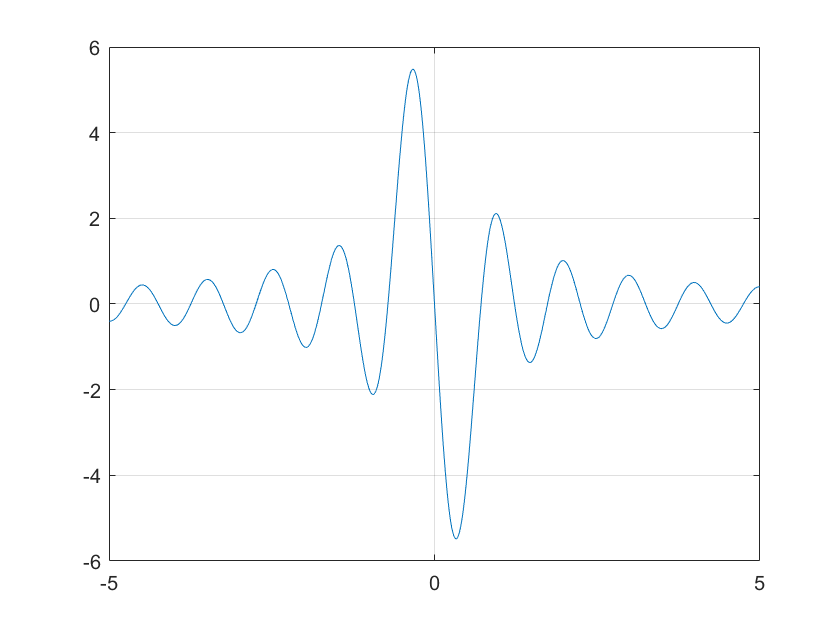

clear all; clc; format shorteng;
fg = 1;
t = linspace(-5, 5, 1e3);

h = @(t) (2.*pi.*fg.*t.*cos(2.*pi.*fg.*t) - sin(2.*pi.*fg.*t) ) ./ (pi.*t.^2);
ht = h(t);
plot(t, ht); grid on;

### b) Um welche Zeit τ muss die Impulsantwort h(t) verschoben werden, damit durch nachfolgende Abtastung mit T = 0.25 s und Multiplikation mit einem Rechteck-Fenster der Länge L ein kausales Filter mit einer symmetrischen Impulsantwort resultiert? Tipp: Unterscheiden Sie, ob L gerade oder ungerade ist. 

Ts = 0.25;
% ungerade:
% Verschieben um: of = (L-1)/2 *T (weil Zeit)

% gerade:
% ?

### c) Bestimmen Sie mit MATLAB wie unter b) beschrieben die Impulsantwort eines entsprechenden Filters mit L = 21 Koeffizienten. 

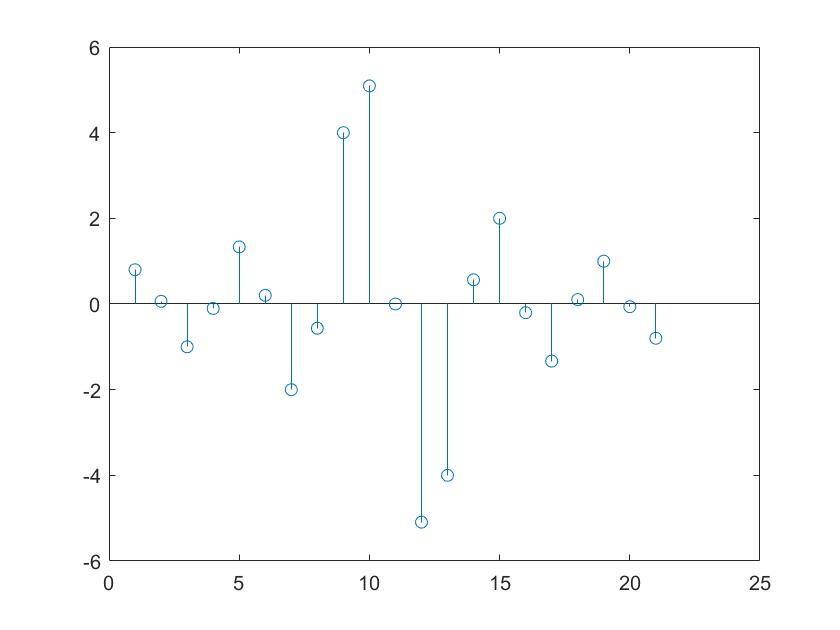

L = 21;
k = -(L-1)/2 : (L-1)/2;

t = k.*Ts;
t = t+eps;
hk = h(t);
stem(hk)

### d) Plotten Sie den Amplitudengang des Filters im Bereich 0 Hz ≤ f ≤ 2 Hz. Entspricht er Ihren Erwartungen?

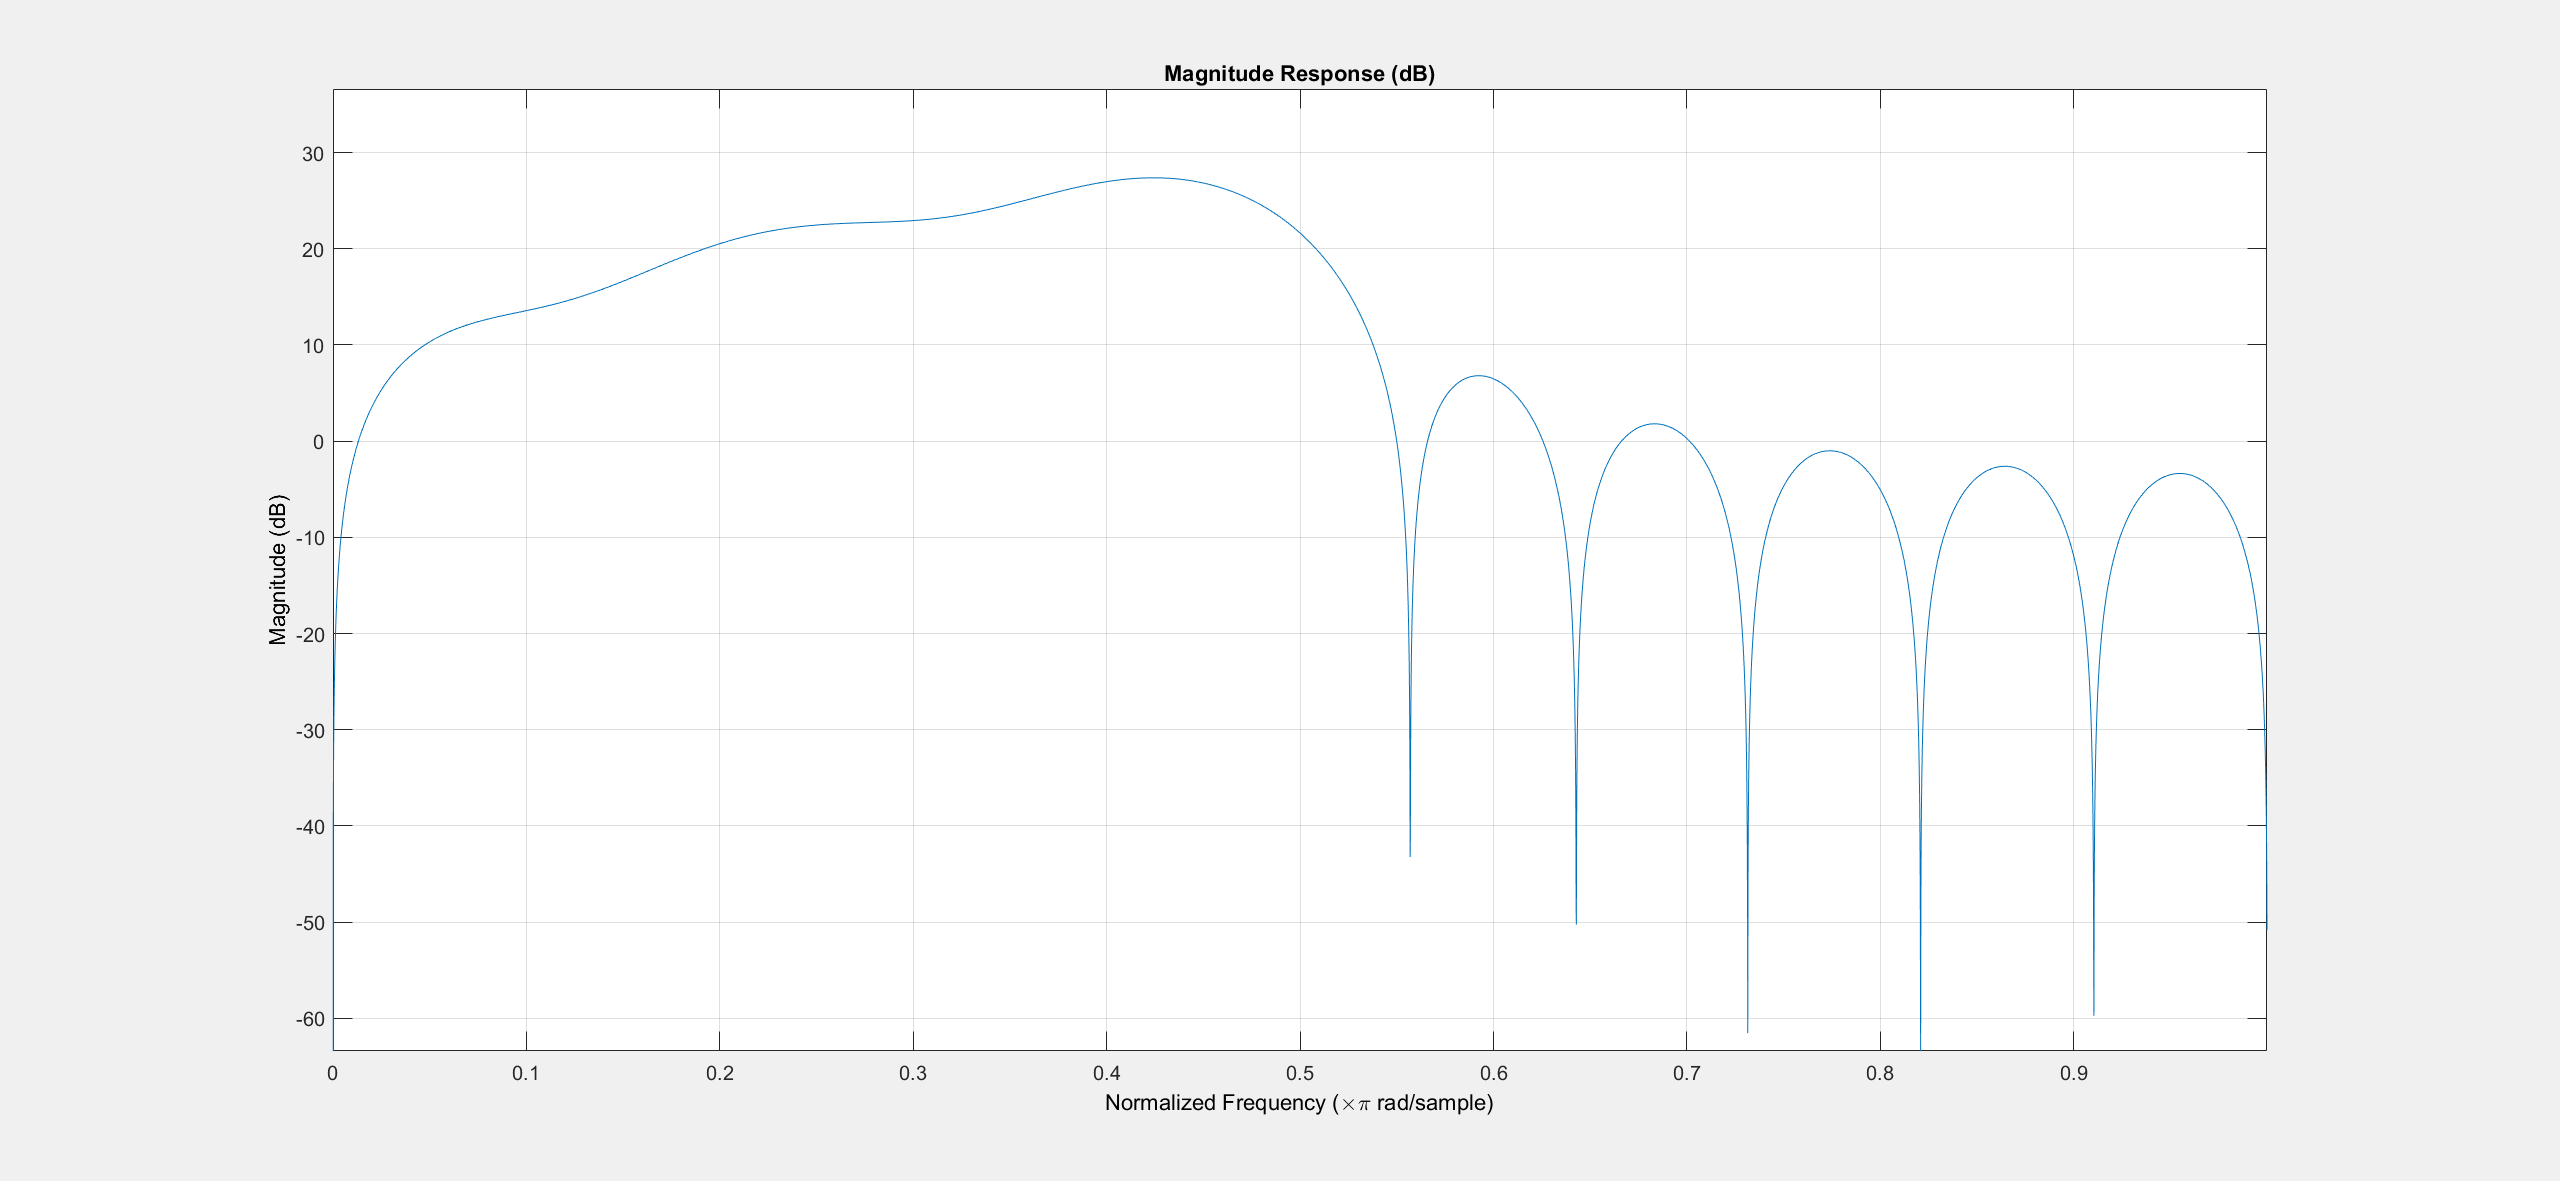

fvtool(hk)

### e) Wiederholen Sie c) und d) mit einem Hamming-Fenster.

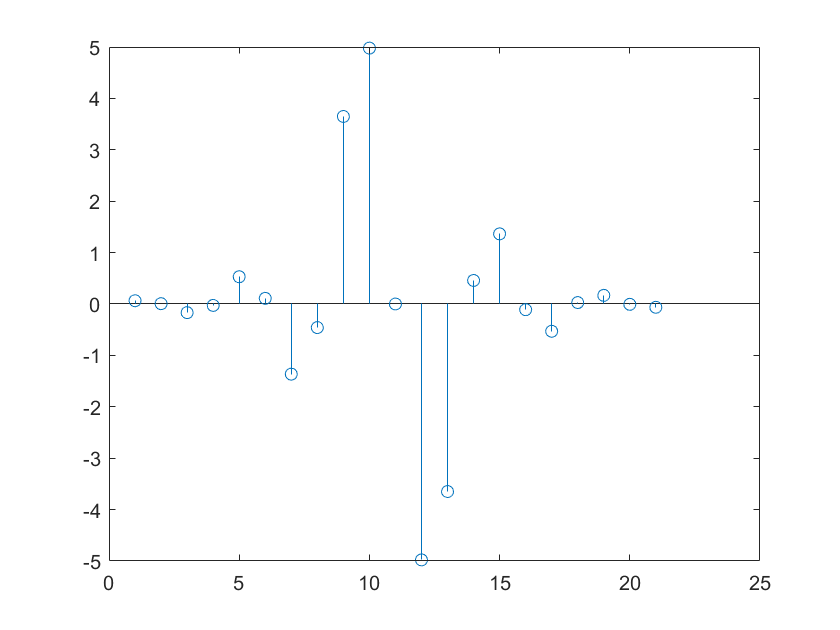

w = hamming(L);
hw = hk.*w';
stem(hw)

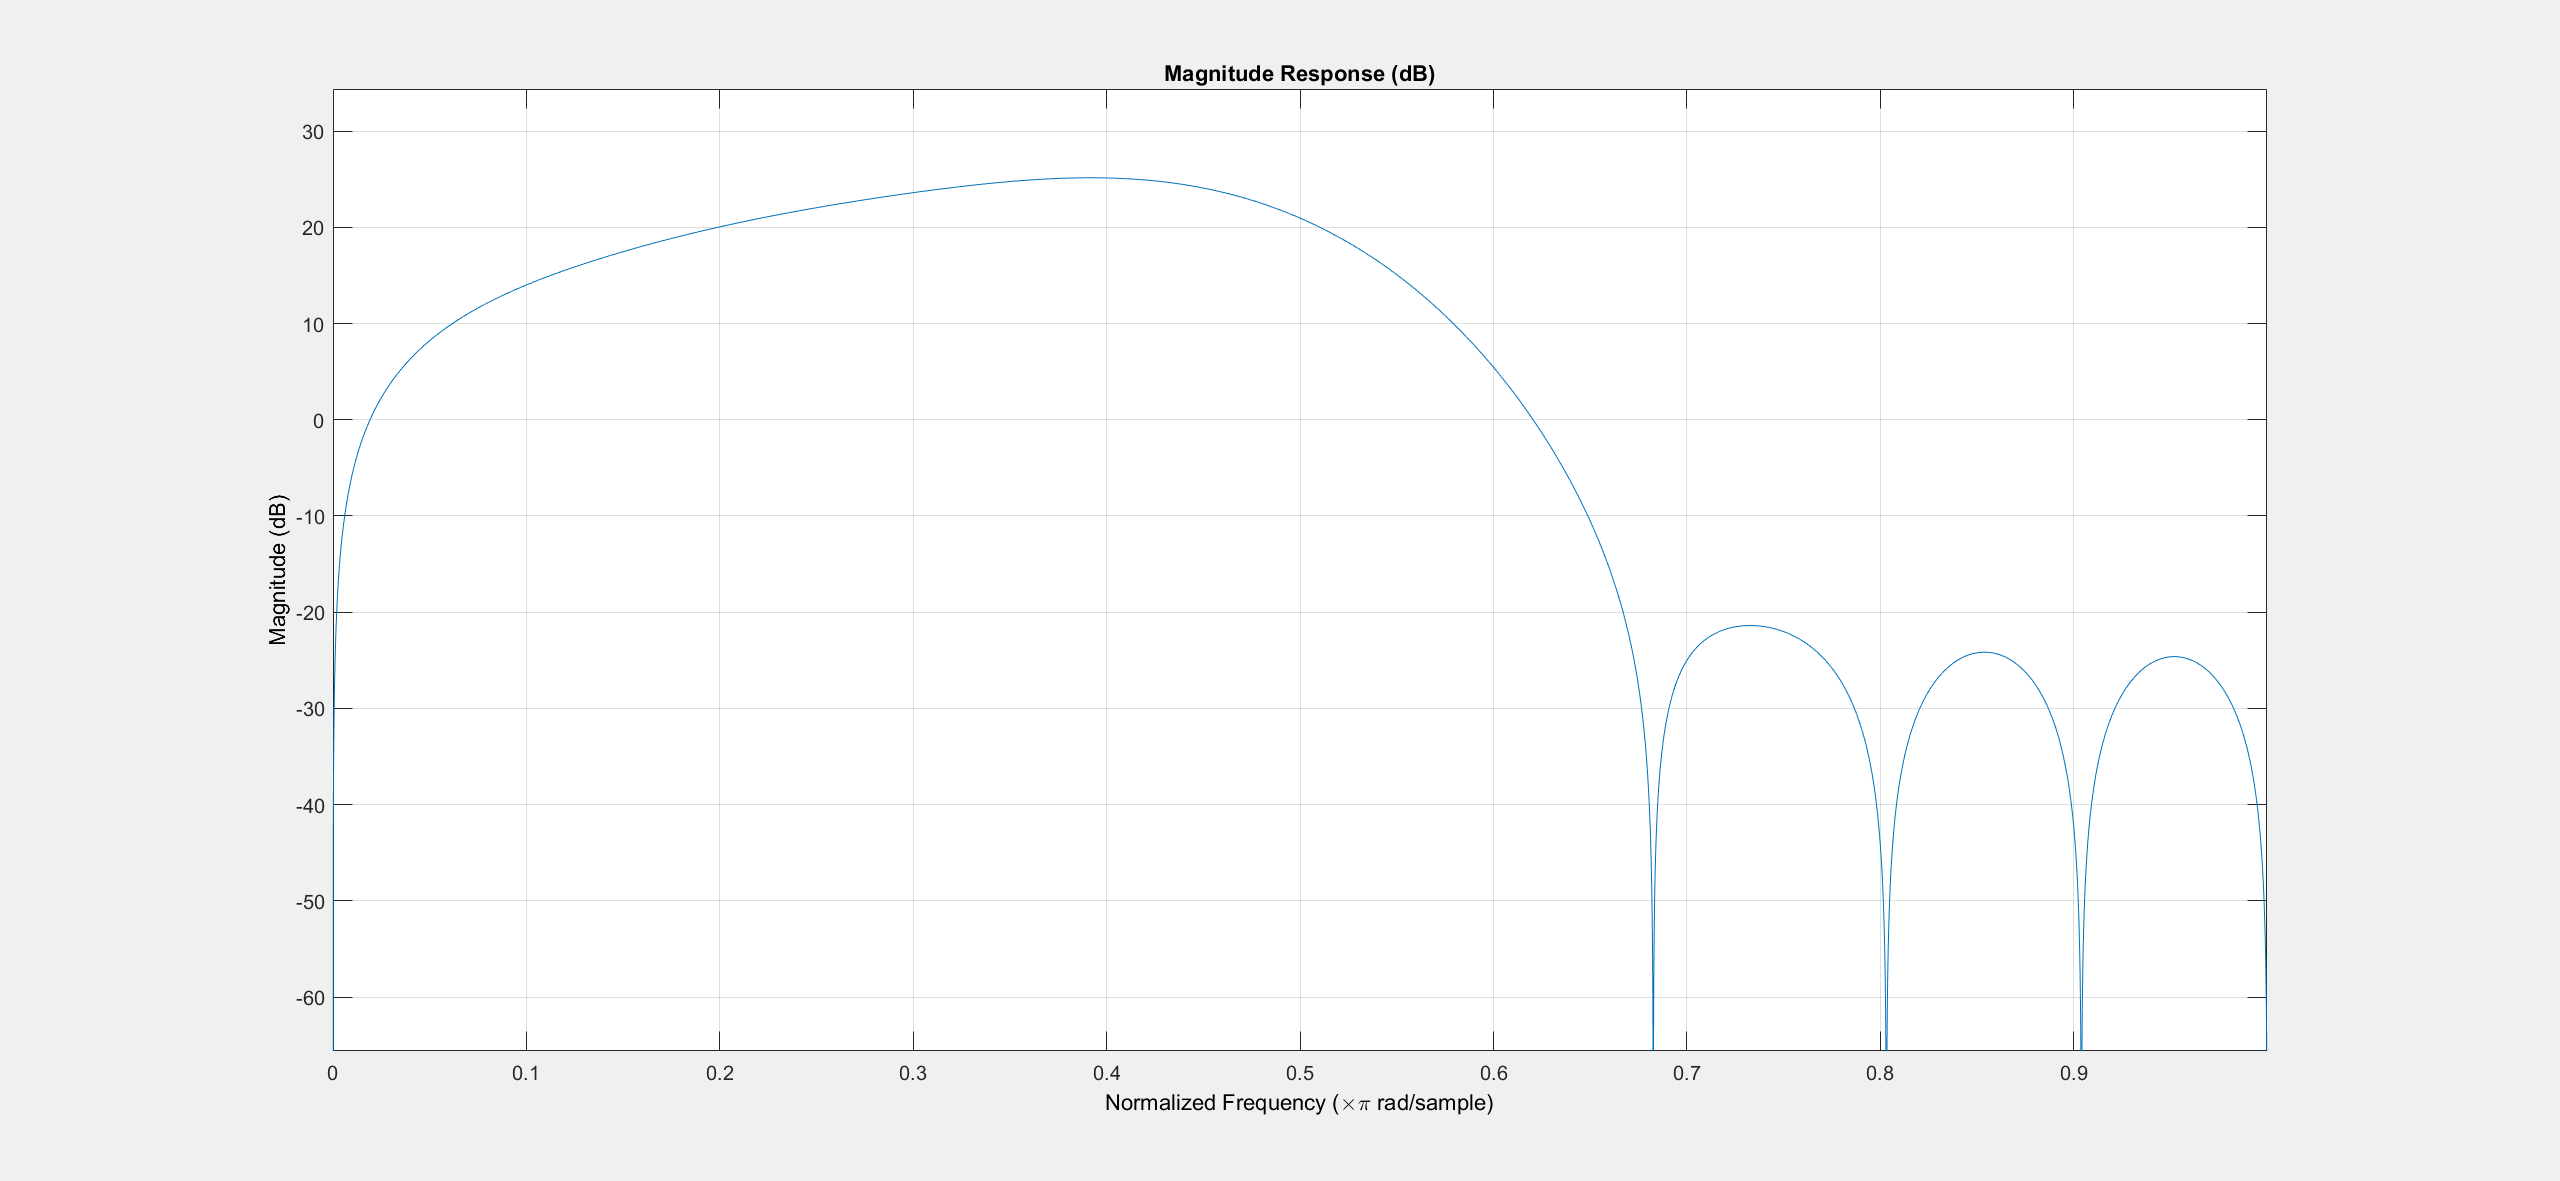


fvtool(hw)

### Aufgabe 3 

Ein FIR-Filter, das die nachfolgende Übertragungsfunktion möglichst gut annähert, soll entworfen werden. [...]

### a) Skizzieren Sie das Spektrum der mit T abgetasteten Impulsantwort. 

clear; clc;


### b) Bestimmen Sie die komplexen Fourierkoeffizienten des unter a) skizzierten Spektrums.

syms f T n
Hf = cos(pi*T*f);

c0 = 1/T*int(Hf, -T/2, T/2)

$$c0 = \frac{2\,\sin\left(\frac{\pi \,T^{2}}{2}\right)}{T^{2}\,\pi }$$

cn = 1/T*int(Hf*exp(j*2*pi*n*f*T), -T/2, T/2)

$$cn = \frac{\sin\left(\pi \,T^{2}\,f\right)\,\cos\left(\pi \,T\,f\right)}{T^{2}\,f\,\pi }$$

% whatever???

### c) Verwenden Sie ein Hamming-Fenster, um ein FIR-Filter mit L = 21 Koeffizienten zu bestimmen, das die gegebene Übertragungsfunktion annähert. 

clear; clc;
hn = 